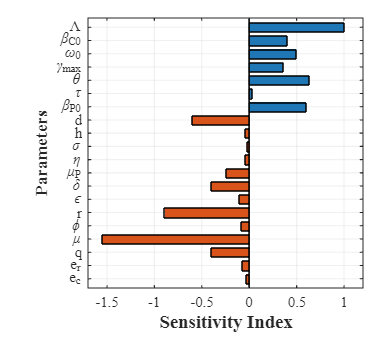


clear; clc; close all;

%% 1. Parameters
parameters = { ...
    '\Lambda', '\beta_{C0}', '\omega_0', ...
    '\gamma_{max}', '\theta', '\tau', ...
    '\beta_{P0}', 'd', 'h', '\sigma', ...
    '\eta', '\mu_P', '\delta', '\epsilon', ...
    'r', '\phi', '\mu', 'q', 'e_r', 'e_c'};

%% 2. Normalized sensitivity indices
SI = [ ...
     1.000,  0.400,  0.500,  0.362, ...
     0.638,  0.038,  0.600, -0.600, ...
    -0.038, -0.022, -0.044, -0.239, ...
    -0.400, -0.100, -0.889, -0.085, ...
    -1.544, -0.399, -0.071, -0.032];

%% 3. Create figure
fig = figure('Color','w', ...
    'Units','centimeters', ...
    'Position',[2 2 17 16]);

ax = axes('Parent',fig);

%% 4. Horizontal bar plot
b = barh(ax,1:length(SI),SI,0.7, ...
    'FaceColor','flat', ...
    'EdgeColor','k', ...
    'LineWidth',0.5);

% Bar colors
blue   = [0.12 0.47 0.71];
orange = [0.85 0.33 0.10];

for i = 1:length(SI)
    if SI(i) >= 0
        b.CData(i,:) = blue;
    else
        b.CData(i,:) = orange;
    end
end

%% 5. Format axes
set(ax, ...
    'YTick',1:length(SI), ...
    'YTickLabel',parameters, ...
    'TickLabelInterpreter','tex', ...
    'YDir','reverse', ...
    'FontName','Times New Roman', ...
    'FontSize',11, ...
    'LineWidth',0.8);

xlabel('Sensitivity Index', ...
    'FontName','Times New Roman', ...
    'FontSize',14, ...
    'FontWeight','bold');

ylabel('Parameters', ...
    'FontSize',13, ...
    'FontWeight','bold');

xlim([-1.7 1.2]);
ylim([0.3 length(SI)+0.7]);

%% 6. Grid
grid on;
box on;

ax.GridColor = [0.85 0.85 0.85];
ax.GridAlpha = 0.4;
ax.Layer = 'bottom';

%% 7. Zero line
hold on;
xline(0,'k-','LineWidth',1.1);
hold off;


% Increase bottom margin to prevent xlabel clipping
ax.Position = [0.23 0.20 0.72 0.75];

%% 9. Export
set(fig,'PaperPositionMode','auto');

print(fig,'Sensitivity_Horizontal', ...
    '-depsc2','-r600');

print(fig,'Sensitivity_Horizontal', ...
    '-dpng','-r600');